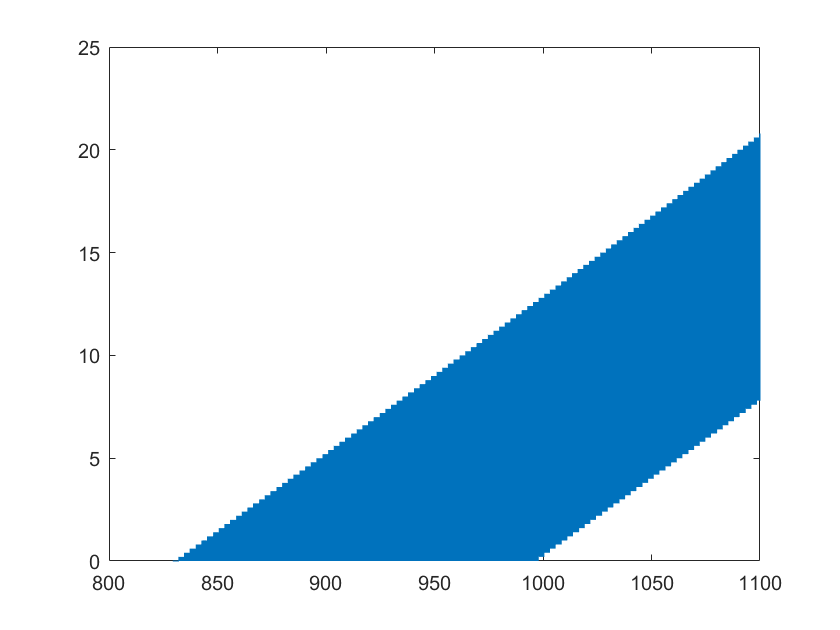

phi_inc = input("Azimuthal angle: ");
m = input("Mode: ");
substrate_RI = input("Substrate RI: ");
cover_RI = input("Cover RI: ");
material_RI = input("Grating material RI: ");
fill_factor = input("Fill factor: ");



theta=[];            % theta vs wavelength
w=[];
for j = phi_inc
    for k= 400:0.2:1100
        for i = 0:0.2:90
            z= effective_RI(i, j, m, k,cover_RI);
            n_w = waveguide_eff_RI(cover_RI, material_RI, fill_factor);
            if z<n_w && z>max(substrate_RI, cover_RI)
                theta=[theta i];
                w=[w k];
            end       
        end
        
    end
     
end

plot(w, theta)

function [n_eff] = effective_RI(theta_inc,phi_inc,m,wavelength,cover_RI)
a= sind(theta_inc);
b= cosd(phi_inc);
c = (m*wavelength)/572;
n_1 = cover_RI;
t_1 = (n_1*a);
t_2 = 2*t_1*b*c;
t_3 = c^2;
n_eff = sqrt((t_1^2)-t_2+t_3);
end

function [nw] = waveguide_eff_RI(nl, nh, fill)
nw = 1/(sqrt((fill/(nh^2)) + ((1-fill)/(nl^2))));
end